# FORWARD KINEMATICS

José Torres Garcia & Iván López Buira **[G11 - F]**

## Write a Live script file (.mlx) 

## 1) Draw on top of the figure de necessary frame 

## 2) Derive the DH parameters table and the neighboring homogeneous transformation matricesi−1 Ti, for i=1,2,3, as functions of the joint angles 

## 3) Implement the forward kinematics, that is T Ts, 

## 4) Calculate the result for the following joint angles: (0, 0, 0), (0, π/2, 0), and (0, π/2, π/6).

## FRAMES

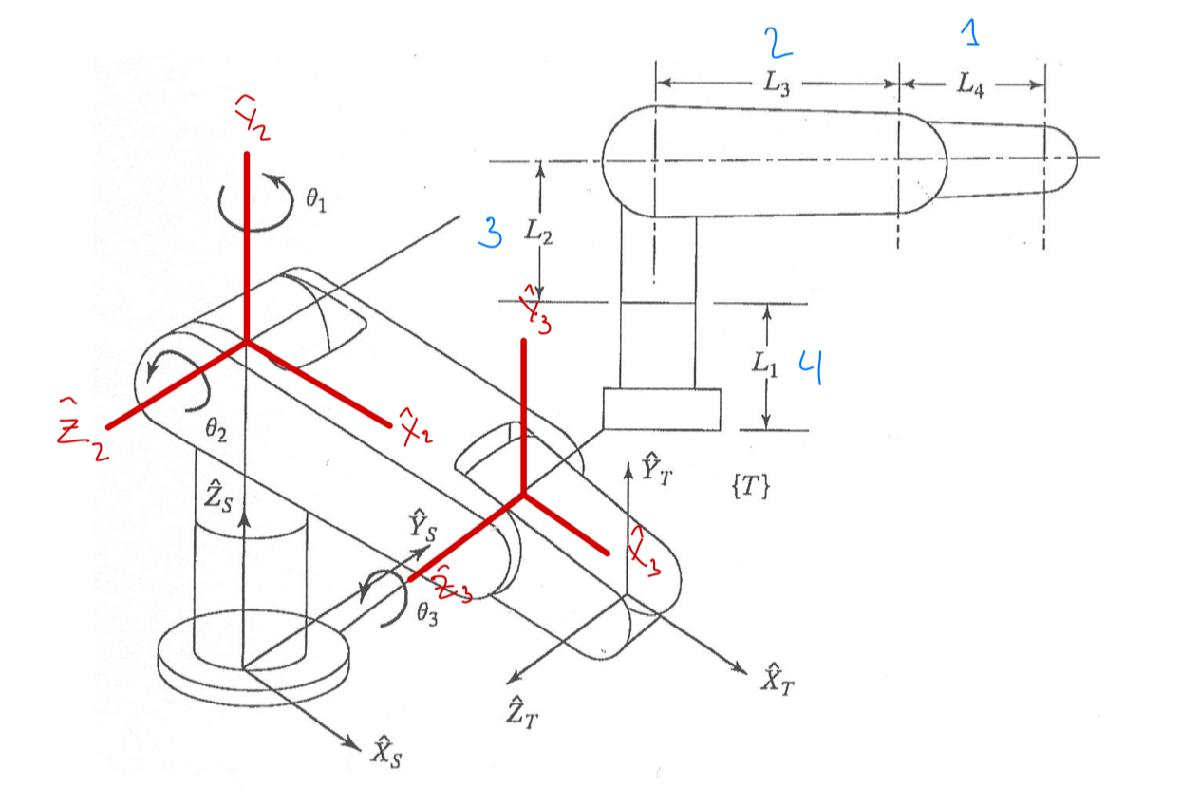

## **DH PARAMETERS**

clear
mdl_3L_me
p3LCraigh

 
p3LCraigh = 
 
3L-Craigh-Ivan&Jose [Unimation]:: 3 axis, RRR, stdDH, slowRNE    
 - Craigh;                                                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          7|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


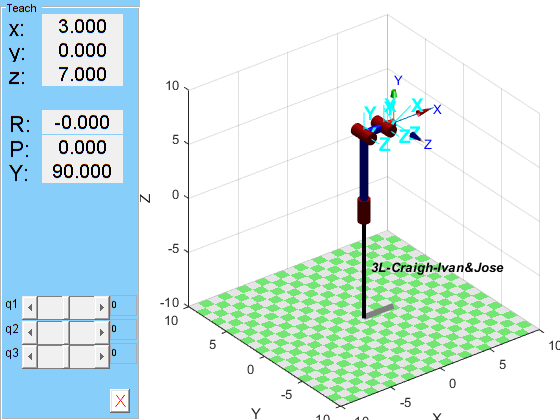

figure
p3LCraigh.plot([0,0,0],'zoom',1.5)

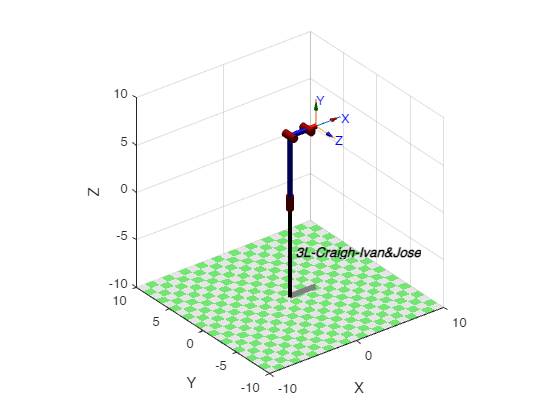

hold off 

## **IMPLEMENT **${}^TT_S$

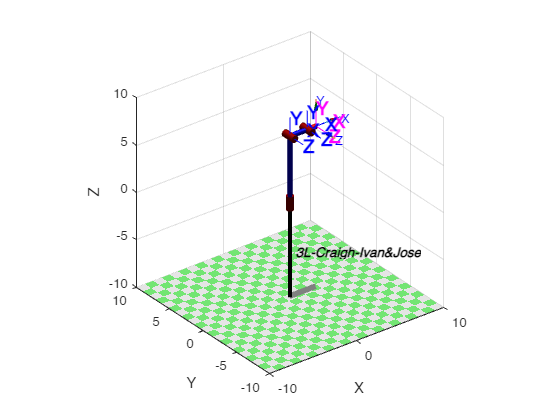

T_S_T = eye(4);
T_2_3 = T_S_T * link_A_B_Std(pi/2, 0, 7, 0);
T_1_2 = T_2_3 * link_A_B_Std(0, 2, 0, 0);
T_0_1 = T_1_2 * link_A_B_Std(0, 1, 0, 0);

T_EE_HANDMADE = T_0_1;

hold on
trplot(T_EE_HANDMADE, 'length', 2, 'width', 0.5, 'color', 'magenta', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2_3, 'length', 2, 'width', 0.5, 'color', 'blue', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2, 'length', 2, 'width', 0.5, 'color', 'blue', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off

a) (0,0,0)

clf
p3LCraigh.teach

hold on
T_2_3_a = T_2_3 * trotz(0);
T_1_2_a = T_1_2 * trotz(0);
T_0_1_a = T_0_1 * trotz(0);

T_S_T_a = T_0_1_a * T_1_2_a * T_2_3_a

T_S_T_a =      1     0     0     5
     0     0     1    -7
     0    -1     0     0
     0     0     0     1


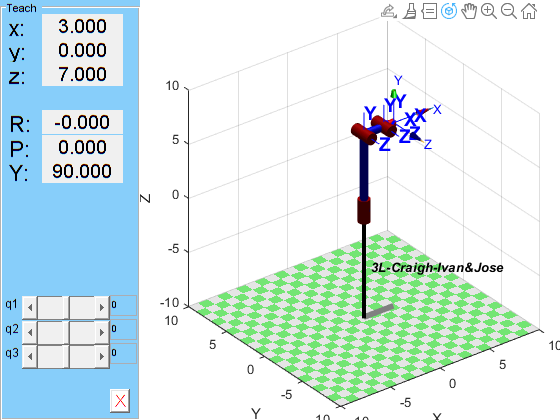

%trplot(T_EE_HANDMADE, 'length', 2, 'width', 0.5, 'color', 'magenta', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_2_3_a, 'length', 2, 'width', 0.5, 'color', 'blue', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_a, 'length', 2, 'width', 0.5, 'color', 'blue', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_0_1_a, 'length', 2, 'width', 0.5, 'color', 'blue', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

T_EE_1 = p3LCraigh.fkine([0,0,0])

 

T_EE_1 = 
         1         0         0         3
         0         0        -1         0
         0         1         0         7
         0         0         0         1


b) (0,π /2,0)

clf
p3LCraigh.teach

hold on
T_2_3_b = T_2_3 * trotz(0);
T_1_2_b = T_1_2 * trotz(pi/2);
T_0_1_b = T_0_1 * trotz(0);

T_S_T_b = T_0_1_b * T_1_2_b * T_2_3_b

T_S_T_b =      0     0     1     5
    -1     0     0    -7
     0    -1     0     0
     0     0     0     1


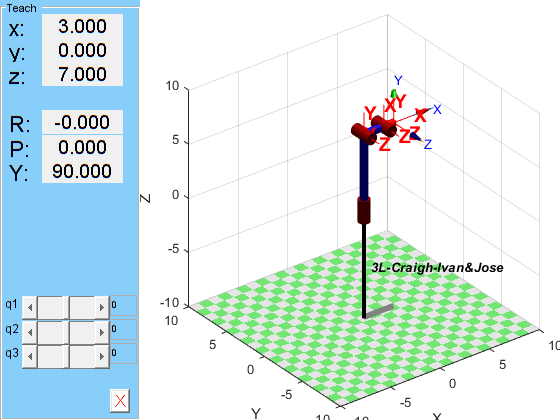

trplot(T_2_3_b, 'length', 2, 'width', 0.5, 'color', 'red', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_b, 'length', 2, 'width', 0.5, 'color', 'red', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_0_1_b, 'length', 2, 'width', 0.5, 'color', 'red', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off

c) (0,π/2,π/6)

clf
p3LCraigh.teach

hold on
T_2_3_c = T_2_3 * trotz(0);
T_1_2_c = T_1_2 * trotz(pi/2);
T_0_1_c = T_0_1 * trotz(pi/6);

T_S_T_c = T_0_1_c * T_1_2_c * T_2_3_c

T_S_T_c =          0    0.5000    0.8660    8.2321
   -1.0000         0         0   -7.0000
         0   -0.8660    0.5000    1.9378
         0         0         0    1.0000


trplot(T_2_3_c, 'length', 2, 'width', 0.5, 'color', 'cyan', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_1_2_c, 'length', 2, 'width', 0.5, 'color', 'cyan', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T_0_1_c, 'length', 2, 'width', 0.5, 'color', 'cyan', 'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

## Used Functions

function T_b_a=link_A_B_Std(alpha,a,d,theta)
T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end